z_re =     2.7662
    2.8411
    2.8523
    2.9324
    3.0248
    2.8615
    2.9578
    2.8811
    2.8673
    2.7828


z_im =    -0.1188
   -0.5445
   -0.1718
   -0.0708
   -0.3762
   -0.3217
   -0.2511
   -0.3555
   -0.4390
   -0.5493


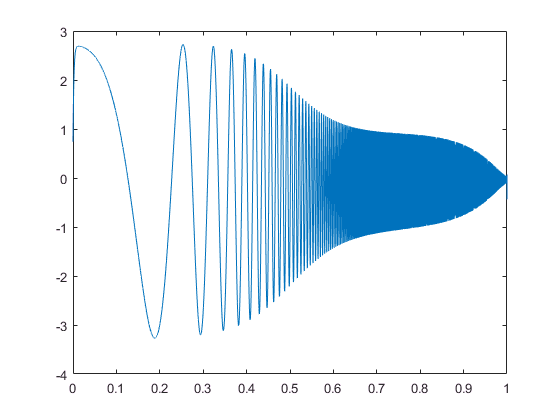

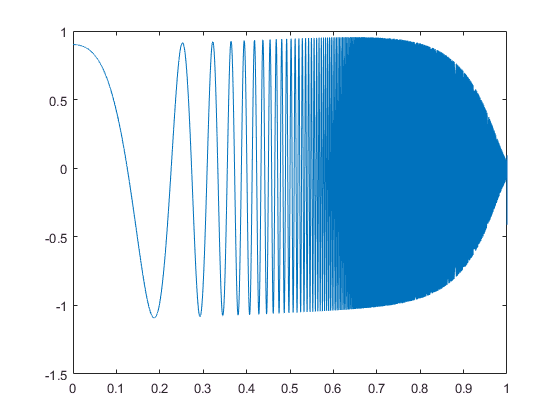

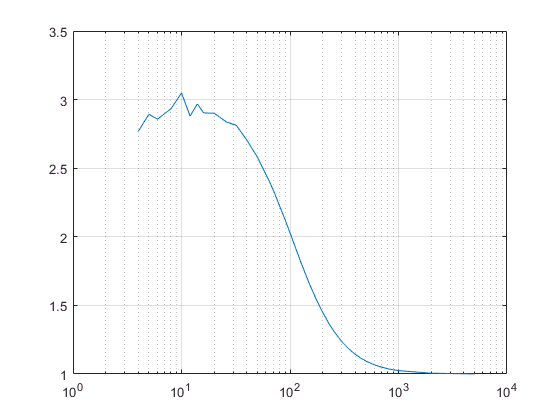

x = ScopeData.signals.values;
y = ScopeData1.signals.values;
x_noise = awgn(x, 100, 'measured', 10);

[z_re, z_im] = chirp_imp(x_noise, y)

 csvwrite('cct13.csv', [z_re, -z_im]);